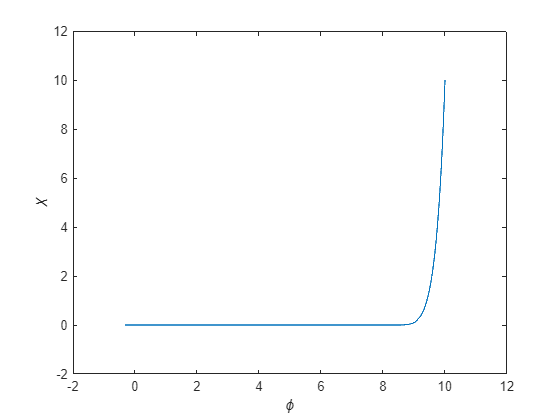

m_phi=1;
m_chi=6;
x0 = [10; 0; 10; 0];
options = odeset('RelTol', 1e-6);
[t1, y1] = ode45(@apolloeq, [0, 600], x0, options);
phi=y1(:,1);
phi_dot=y1(:,2);
chi=y1(:,3);
chi_dot=y1(:,4);
plot(phi, chi);
xlabel('\phi');ylabel('\chi');axis([-2,12,-2,12])

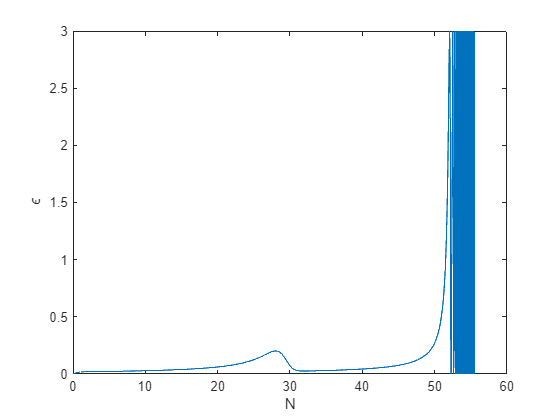

N=zeros(size(t1,1),1);
Hsq=1/6*(phi_dot.^2+chi_dot.^2+m_phi^2*phi.^2+m_chi^2*chi.^2);
for i=1:size(t1,1)-1
    N(i+1)=N(i)+Hsq(i).^0.5.*(t1(i+1)-t1(i));
end
Hdot=-1/2*(phi_dot.^2+chi_dot.^2);
eps=-Hdot./Hsq;
plot(N,eps)
ylabel('\epsilon');xlabel('N');

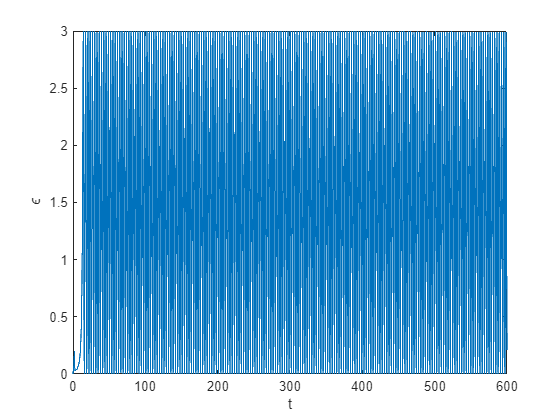

plot(t1,eps)
ylabel('\epsilon');xlabel('t');

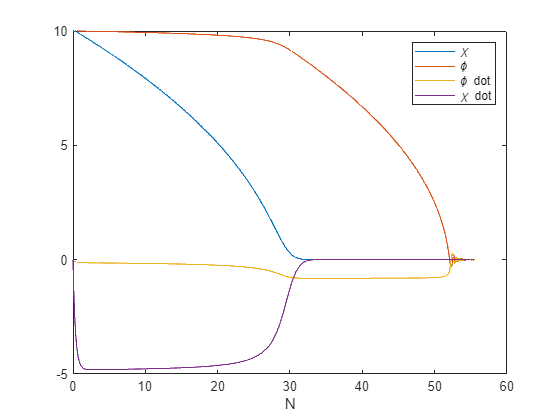

plot(N,chi)
hold on
plot(N,phi)
plot(N,phi_dot)
plot(N,chi_dot)
hold off
legend('\chi','\phi','\phi dot','\chi dot')
xlabel('N')

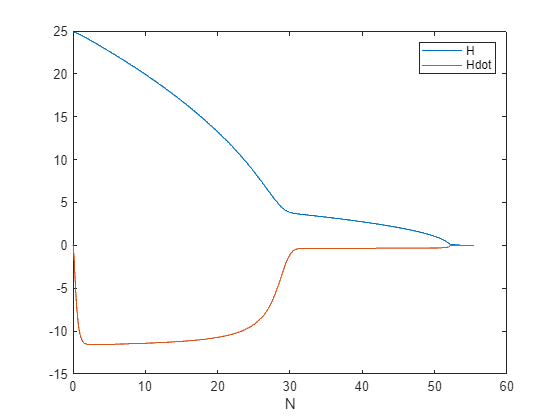

plot(N,Hsq.^0.5)
hold on 
plot(N,Hdot)
hold off
legend('H','Hdot')
xlabel('N')



function dx = apolloeq(t, x)
    m_phi=1;
    m_chi=6;
    
    Hsq=1/6*(x(2)^2+x(4)^2+m_phi^2*x(1)^2+m_chi^2*x(3)^2);
    dx = [x(2);
          -3*Hsq^0.5*x(2)-m_phi^2*x(1);
         x(4);
          -3*Hsq^0.5*x(4)-m_chi^2*x(3)];
end

